clear;clc;



%
%

Plot all the best


S = load(['C:\Users\Will\OneDrive\MyMatlab\MetaMetric\Debugging\' ...
    'ResultVerification\alphaOpic\CH11_Optims.mat']);
% T_Zmax = S.A_max;
writetable(S.A_max, 'zandi_11ch_maxMel_cctSweep_duv0.csv')
writetable(S.A_min, 'zandi_11ch_minMel_cctSweep_duv0.csv')


T_Zmax_sub = getTableFromZandi(S.A_max);
T_Zmin_sub = getTableFromZandi(S.A_min)

T_Zmin_sub = 17×5 table
    CCT_Actual    Duv_Target    MelanopicEDI_250lx    MelanopicDER_250lx    melOpicELR
    __________    __________    __________________    __________________    __________

      2686.9          0               96.509               0.38604           0.51196  
      2813.1          0               102.21               0.40883            0.5422  
      2904.1          0               103.71               0.41486           0.55019  
      2992.3          0               107.98               0.43193           0.57283  
      3141.4          0               116.03               0.46412           0.61552  
        3266          0               120.38               0.48153           0.63861  
      3460.4          0               129.89               0.51957           0.68906  
      3643.8          



[myMaxSpd, myMinSpd] = getMyMinMax;

writetable(array2table([ (380:1:780)',myMaxSpd(:,1:4)]),'myMaxSpdZandi.csv')

T_my_min = table();
T_my_max = table();

for idx = 1:width(myMaxSpd)
    S_my_max(idx) = channelPercentsToSPDNestedStruct(myMaxSpd(:,idx));
%     Aopic_my_max(idx,:) = [S_my_max(idx).AOpics];
    t = array2table([S_my_max(idx).Trichromatic.cct,...
        S_my_max(idx).Trichromatic.duv, ...
        S_my_max(idx).AOpics.melOpicELR ],VariableNames = ["cct","duv","melOpicELR"]);
    T_my_max = [T_my_max; t];


    S_my_min(idx) = channelPercentsToSPDNestedStruct(myMinSpd(:,idx));
    t = array2table([S_my_min(idx).Trichromatic.cct,...
        S_my_min(idx).Trichromatic.duv, ...
        S_my_min(idx).AOpics.melOpicELR ],VariableNames = ["cct","duv","melOpicELR"]);
    T_my_min = [T_my_min; t];
%     Aopic_my_min(idx,:) = [S_my_min(idx).AOpics];

end
% T_my_min.Properties.VariableNames = [""]

T_my_min

T_my_min = 17×3 table
     cct          duv        melOpicELR
    ______    ___________    __________

    2686.9    -2.1331e-10     0.49085  
    2813.1              0     0.51931  
    2904.1              0     0.53961  
    2992.3     6.3012e-12     0.55968  
    3141.4              0      0.5914  
      3266              0     0.61802  
    3460.4              0     0.65868  
    3643.8              0     0.69596  
    3819.9              0     0.73055  
    4125.5              0     0.78994  
    4378.1              0     0.83838  
      4699              0     0.89513  
    5159.4              0     0.96611  
    5538.5     2.8761e-12      1.0153  
    6096.9    -2.5724e-12       1.081  
    6738.1              0      1.1468  


T_my_max

T_my_max = 17×3 table
     cct          duv        melOpicELR
    ______    ___________    __________

    2686.9      5.684e-10     0.74383  
    2813.1              0     0.78574  
    2904.1              0     0.81563  
    2992.3              0     0.84257  
    3141.4              0     0.88863  
      3266              0     0.92487  
    3460.4              0     0.97974  
    3643.8     2.5724e-12      1.0289  
    3819.9              0      1.0733  
    4125.5    -5.1449e-12      1.1482  
    4378.1              0      1.2081  
      4699              0      1.2772  
    5159.4              0      1.3623  
    5538.5              0      1.4209  
    6096.9              0      1.4981  
    6738.1     1.8007e-11      1.5749  


% spd_my_min = [S_my_min.Power.s]
% spd_my_max = [S_my_max.Power.s]



Plot comparison

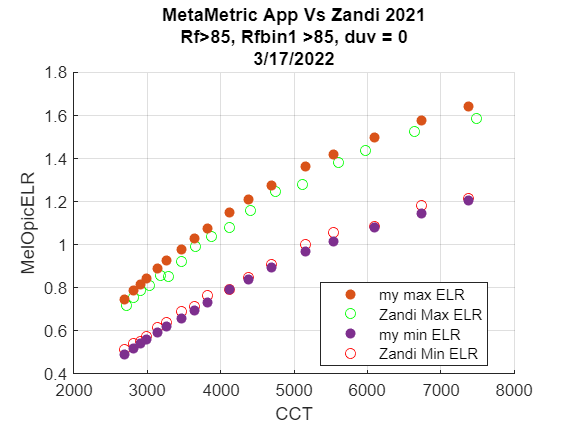


zandiCompare = figure;clf;
zandiMaxPlot = scatter(T_Zmax_sub{:,"CCT_Actual"},T_Zmax_sub{:,"melOpicELR"},'g' );
hold on
myMaxPlot = scatter(T_my_max{:,"cct"}, T_my_max{:,"melOpicELR"} ,'filled');

zandiMinPlot = scatter(T_Zmin_sub{:,"CCT_Actual"},T_Zmin_sub{:,"melOpicELR"},'r' );
myMinPlot = scatter(T_my_min{:,"cct"}, T_my_min{:,"melOpicELR"} ,'filled');

legend([myMaxPlot, zandiMaxPlot, myMinPlot, zandiMinPlot], ...
    ["my max ELR", "Zandi Max ELR", "my min ELR", "Zandi Min ELR"],'Location','best')
title("MetaMetric App Vs Zandi 2021" + newline() + "Rf>85, Rfbin1 >85, duv = 0" + newline() + "3/17/2022");
grid on;ylabel("MelOpicELR");xlabel("CCT");

function [SpdMaxBest,SpdMinBest]=getMyMinMax
load(['C:\Users\Will\OneDrive\MyMatlab\MetaMetric\Debugging\' ...
    'ResultVerification\alphaOpic\compareNature11CH_Max_safe.mat'])



Smax = SolutionArray;
Smax = Smax( [Smax.rf]>85);
Smax = Smax( min([Smax.s]>=0) );

load(['C:\Users\Will\OneDrive\MyMatlab\MetaMetric\Debugging\' ...
    'ResultVerification\alphaOpic\compareNature11CH_Min_safe.mat'])

Smin = SolutionArray;
Smin = Smin( [Smin.rf]>85);
Smin = Smin( min([Smin.s]>=0) );
%%


myCCTs = unique([round([Smin.cct]), round([Smax.cct]) ]);
for i = 1:numel(myCCTs)
    SminTemp = Smin( round([Smin.cct]) == myCCTs(i) );
    [~, idxBestMin] = min([SminTemp.melOpicDER]);
    SminBest(i) = SminTemp(idxBestMin);

    SmaxTemp = Smax( round([Smax.cct]) == myCCTs(i) );
    [~,idxBestMax] = max([SmaxTemp.melOpicDER]);
    SmaxBest(i) = SmaxTemp(idxBestMax);
end

SpdMaxBest = [SmaxBest.s];
SpdMinBest = [SminBest.s];

end

Get my metrics with new function

function [T_sub] = getTableFromZandi(TableIn)
%% Get Zandi Max
varIsWl = contains(TableIn.Properties.VariableNames,'Nm');
Spd_Zmax = TableIn{:,varIsWl}';
for idx = 1:width(Spd_Zmax)
    Sout(idx) = channelPercentsToSPDNestedStruct(Spd_Zmax(:,idx));
    mel(idx,1) = Sout(idx).AOpics.melOpicELR;
end

T_sub = TableIn(:,["CCT_Actual","Duv_Target","MelanopicEDI_250lx","MelanopicDER_250lx"] );
T_sub = [T_sub, array2table(mel,VariableNames="melOpicELR")];
% T_max_sub = [T_max_sub, ]
% S_max = A_Zmax'

%%
end
% for idx = 1:numel(SminBest)
%     stemp = SminBest(idx).s;
%     stempOut = channelPercentsToSPDNestedStruct(stemp);
%     SminAopic(idx) = stempOut.AOpics;
%     SminCCT(idx,1) = stempOut.Trichromatic.cct;
%     Sminduv(idx,1) = stempOut.Trichromatic.duv;
%     SminLux(idx,1) = stempOut.Trichromatic.spd10degY;
% end
% Tmin_Aopic = struct2table(SminAopic)
% t = array2table([SminLux, SminCCT, Sminduv], "VariableNames", ["Y10","CCT","Duv"]);
% Tmin = [Tmin_Aopic, t];
% %%
% end
